# Training Donkey Car's deep learning model in MATLAB

## Introduction

[DonkeyCar](https://www.donkeycar.com/) is an open source AI car that uses Python-based Keras and TensorFlow as a deep learning framework. This script use MATLAB's Deep Learning Toolbox to load a DonkeyCar training dataset and try training a deep learning model.

## Required Tools

- MATLAB 2021B 

- [Deep Learning Toolbox](https://jp.mathworks.com/products/deep-learning.html)

## Training data and deep learning model

Use this training data published on GitHub.

[https://github.com/autorope/donkey_datasets/tree/master/circuit_launch_20210716](https://github.com/autorope/donkey_datasets/tree/master/circuit_launch_20210716)

circuit_launch_20210716_1715.tar.gz

Use the following * .h5 file (Keras model) as the base data planning model.

[https://github.com/autorope/donkey_datasets/tree/master/circuit_launch_20210716/models](https://github.com/autorope/donkey_datasets/tree/master/circuit_launch_20210716/models)

## Training data and preparation of deep learning model

### Dataset download

Execute the following MATLAB script to download the DonkeyCar dataset file (* .gz) from GitHub and unzip it under the current folder.

%Download DonkeyCar dataset in GitHub
url = 'https://github.com/autorope/donkey_datasets/raw/master/circuit_launch_20210716/';
tarfile = 'circuit_launch_20210716_1826.tar.gz';
datapath = './murmurpi4_circuit_launch_20210716_1826/data/';%Data Path

if(~exist(datapath,'file')) %if not unzipped
    disp('Wait a few minutes for downloading and unziping.')
    websave('temp.gz',[url tarfile],'Timeout',Inf);
    untar('temp.gz');
end



## Download pre-learned deep learning models

Download Donkey Car's pre-trained deep learning model file (Keras).  pilot_21-08-12_10.h5

%Download Donkeycar deep learning mode
netfile='pilot_21-08-12_10.h5';
websave(netfile,[url 'models/' netfile]);


## Loading a pretrained model

Load the model into the workspace.

donkeyKerasNet = importKerasNetwork(netfile); %Load pre-trained network

## Read catalog file

A list of DonkeyCar driving data is recorded in the * .catalog file. Load the dataset containing the image data file name, steering value, and throttle value into MATLAB. Here, read catalog_4.catalog.

%Import catalog
catalogfile = [datapath 'catalog_4.catalog'];%Catalog file
clear dataset;
js = readlines(catalogfile);
for(i = 1:length(js)-1)
    dataset(i) = jsondecode(js(i));
end

%Set image path
imgfolder = [datapath 'images/'];
imgfiles = {dataset.cam_image_array};
imgpath = {};
for(i = 1:length(imgfiles))
    imgpath{i} = strcat(imgfolder,imgfiles{i});
end

%Create Output Data
ang = [dataset.user_angle];
th = [dataset.user_throttle];

## Training and validation data

Divide the training data and the validation data.

In this script, 70% is used as training data.

%Count trainining and test data
train_split = 0.7;%Split data for training and varidation 
dataN = length(ang);
trainN = round(dataN*train_split);

%Create training data
tmp_im = imageDatastore(imgpath(1:trainN)','Labels',imgfiles(1:trainN)');
tmp_ang = arrayDatastore(ang(1:trainN)');
TrainData = combine(tmp_im,tmp_ang);%Training dataset

%Create test data
tmp_im = imageDatastore(imgpath(trainN+1:dataN)','Labels',imgfiles(trainN+1:dataN)');
tmp_ang = arrayDatastore(ang(trainN+1:dataN)');
ValidationData = combine(tmp_im,tmp_ang);%Validation dataset

## Dataset preview

A sample of the image, steering, and throttle values ��is displayed.

%Dataset preview
figure;
plotN = 6*6;
for(i = 1:plotN)
    no = i*10;
   subplot(sqrt(plotN),sqrt(plotN),i);
    imshow(imread(imgpath{no}));
    title(sprintf('Ang=%.2f,Th=%.2f',ang(no),th(no) ) )
end

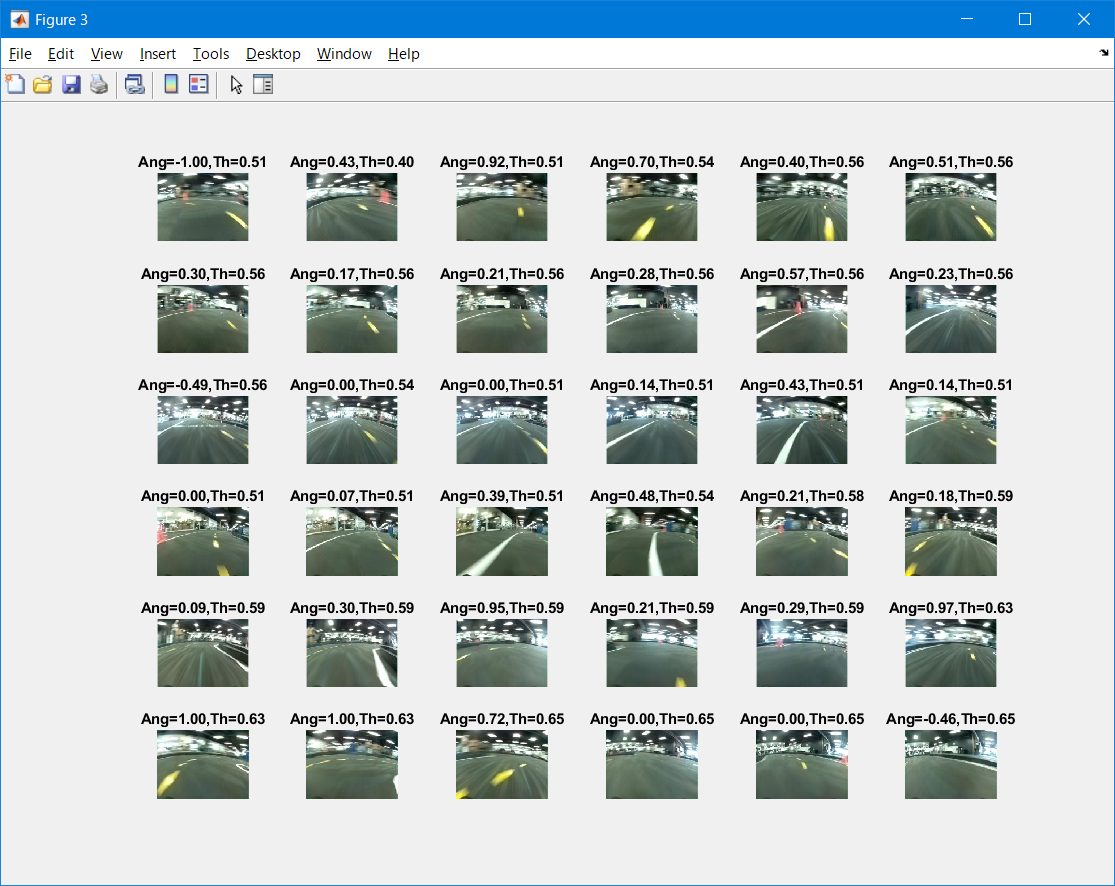

## Model editing and training with Deep Network Designer

Launch Deep Network Designer and load the Donkey Car network from your workspace.

deepNetworkDesigner;

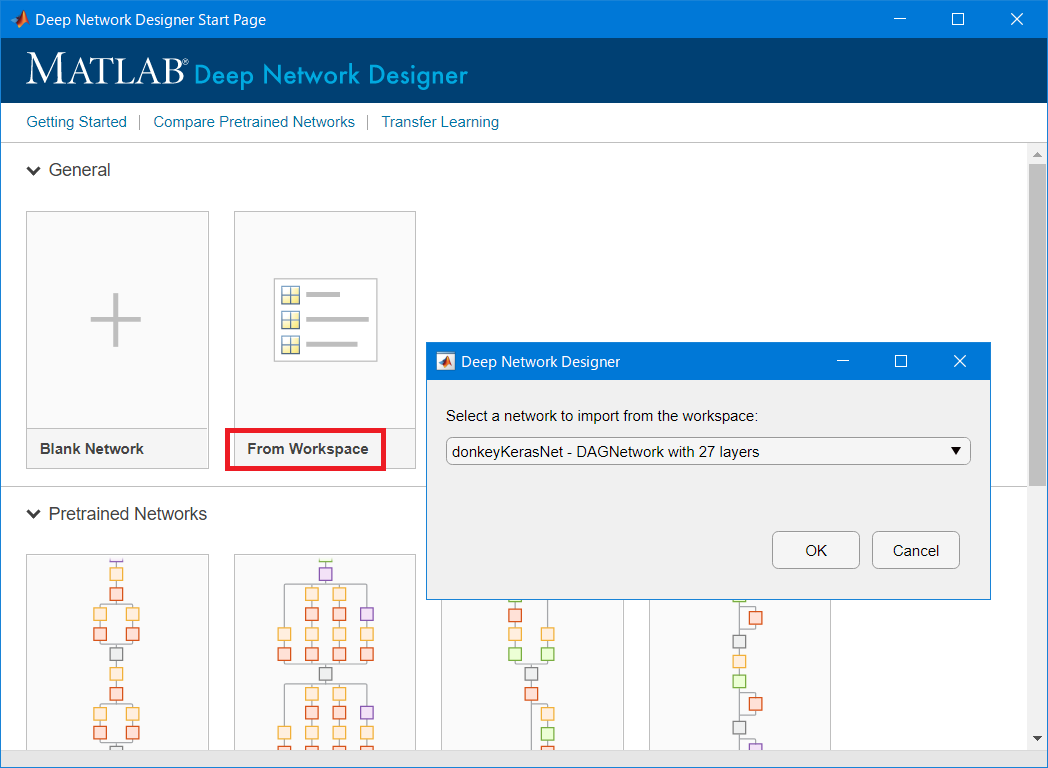

## Editing the network model

Deep Network Designer only supports training for single output networks, so remove one of the output layers.

Click Analyze and verify that there are no errors.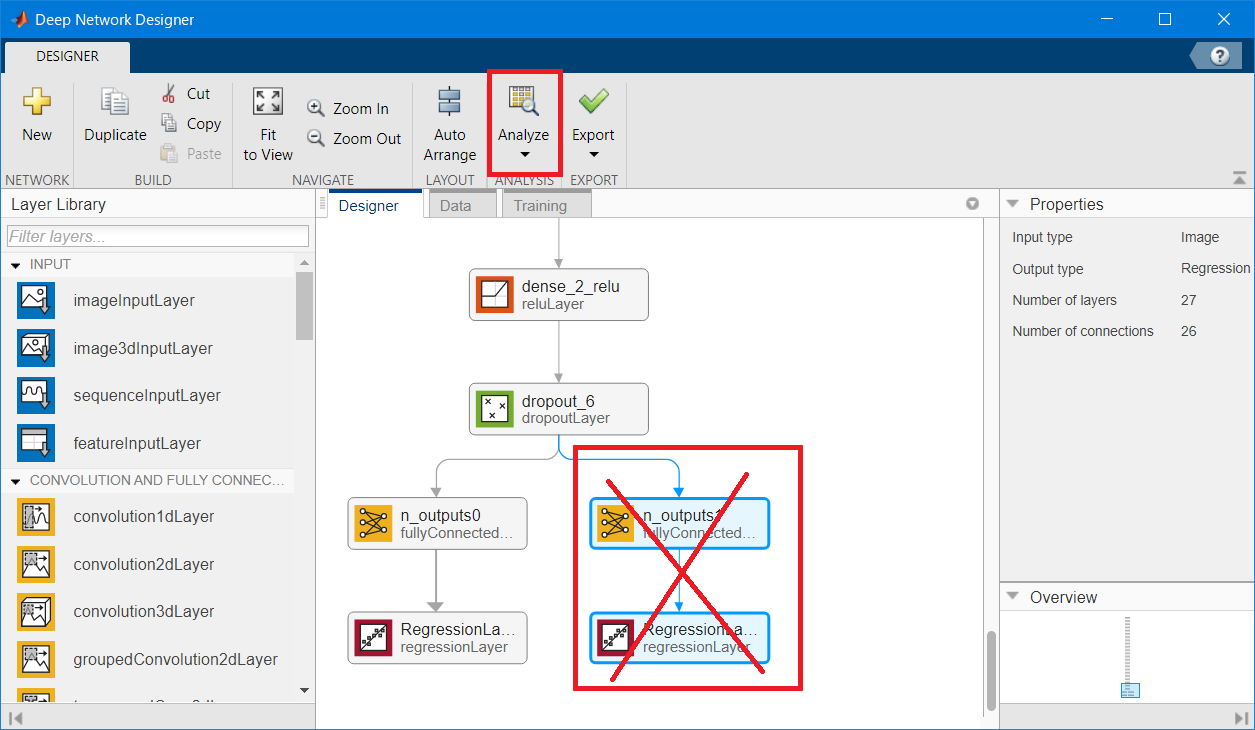

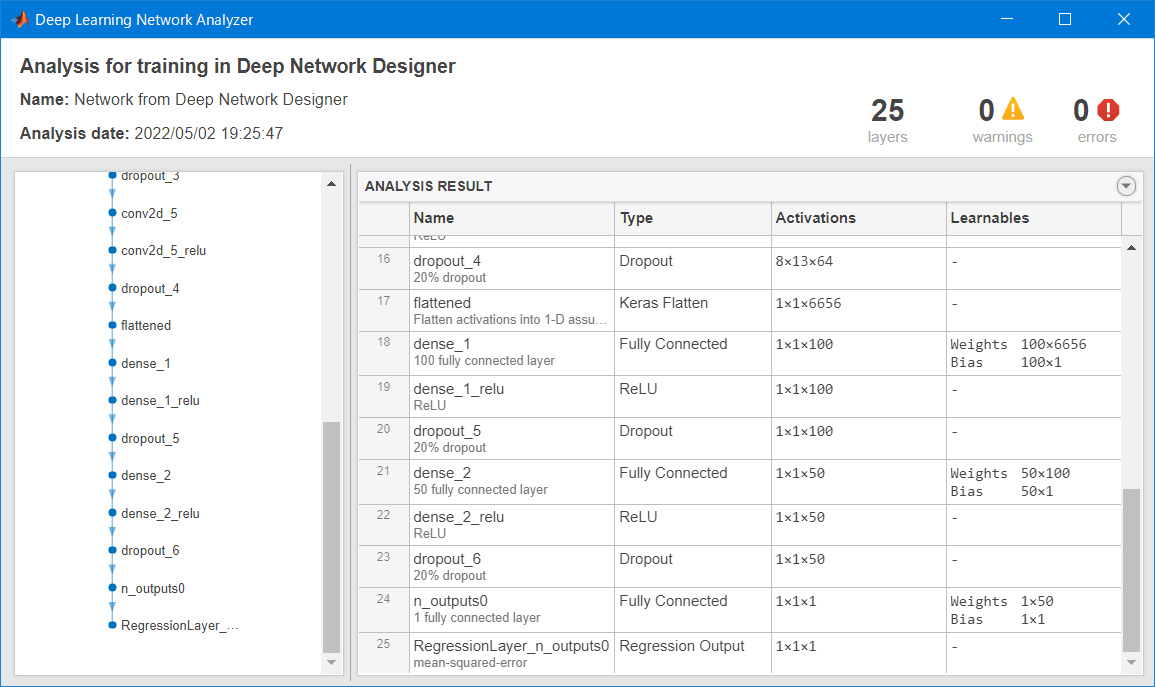

## Training data settings

Click the Data tab, select Import Data> Import Data Store, and set Training Data and Validation Data.

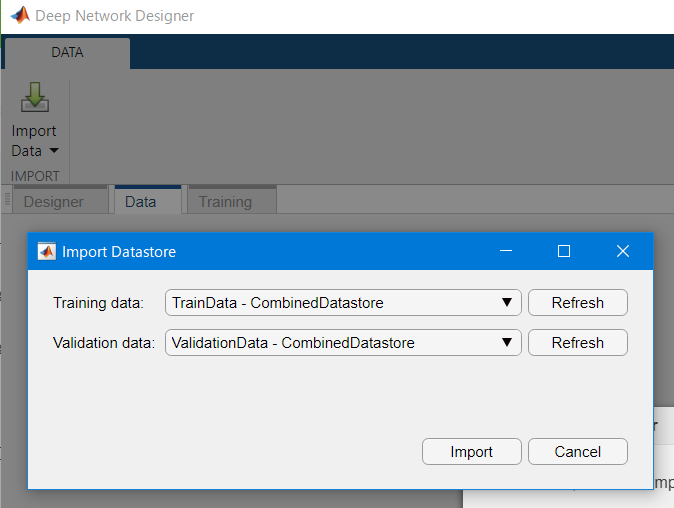

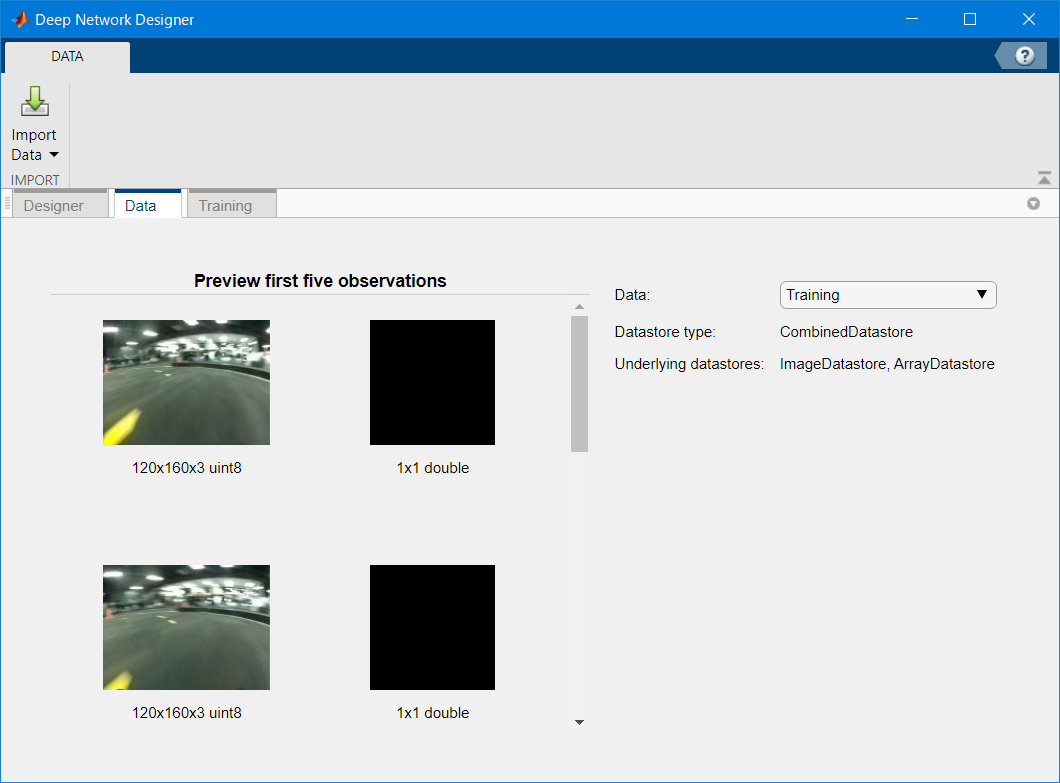

## Training

With the default Training Options settings, click the Train button to learn the network. With this setting, it has diverged. Unfotunaly, changing InitialLearnRate to 0.001 did not improve.😩

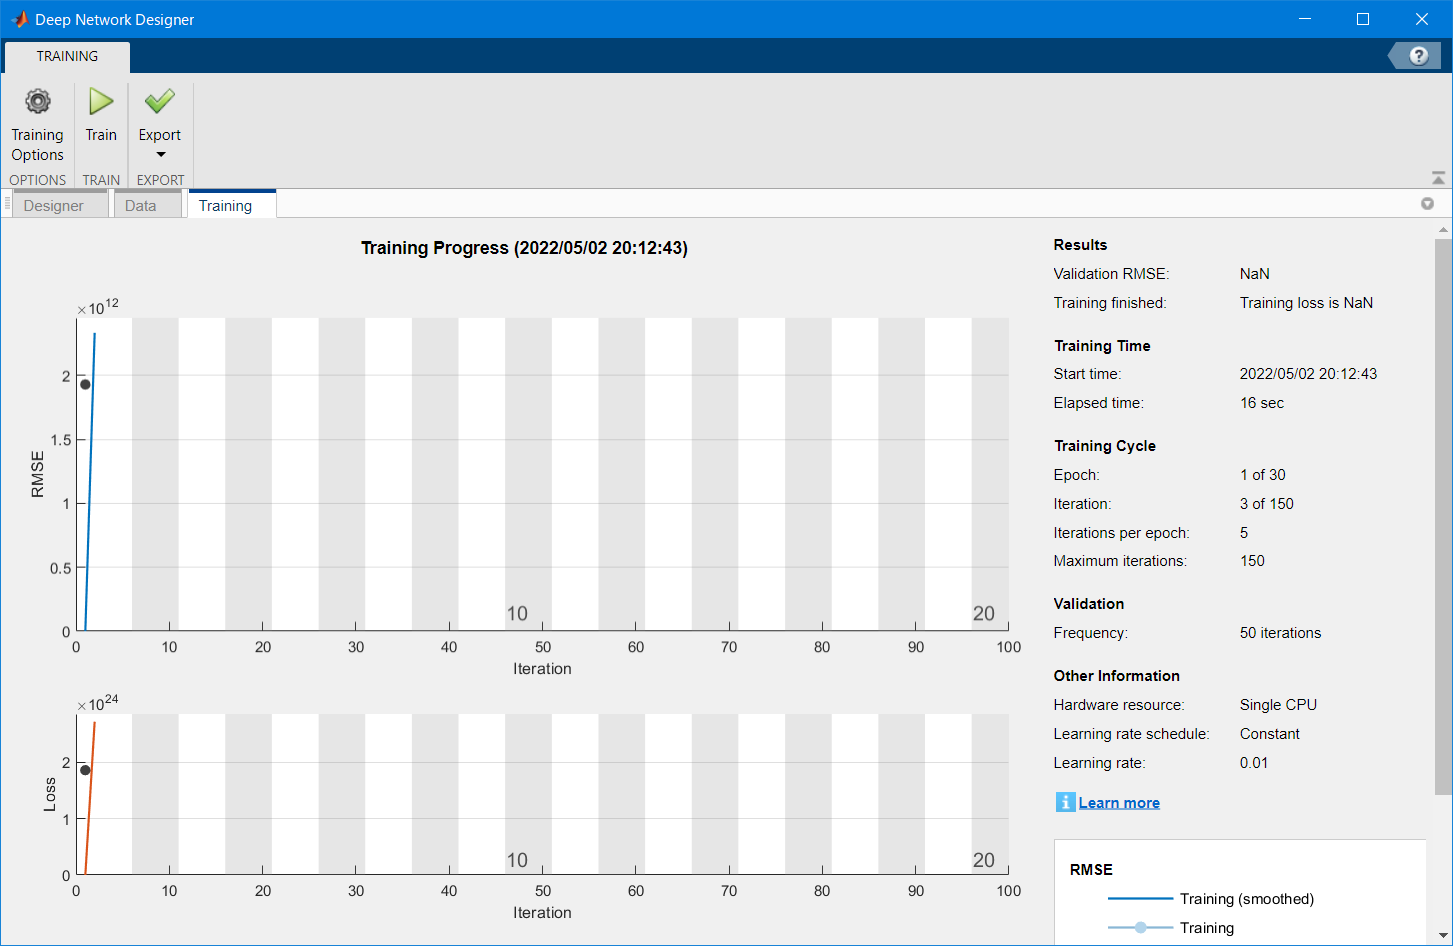

Next, click the Training tab, change Solver to adam in Training Options, and try learning.

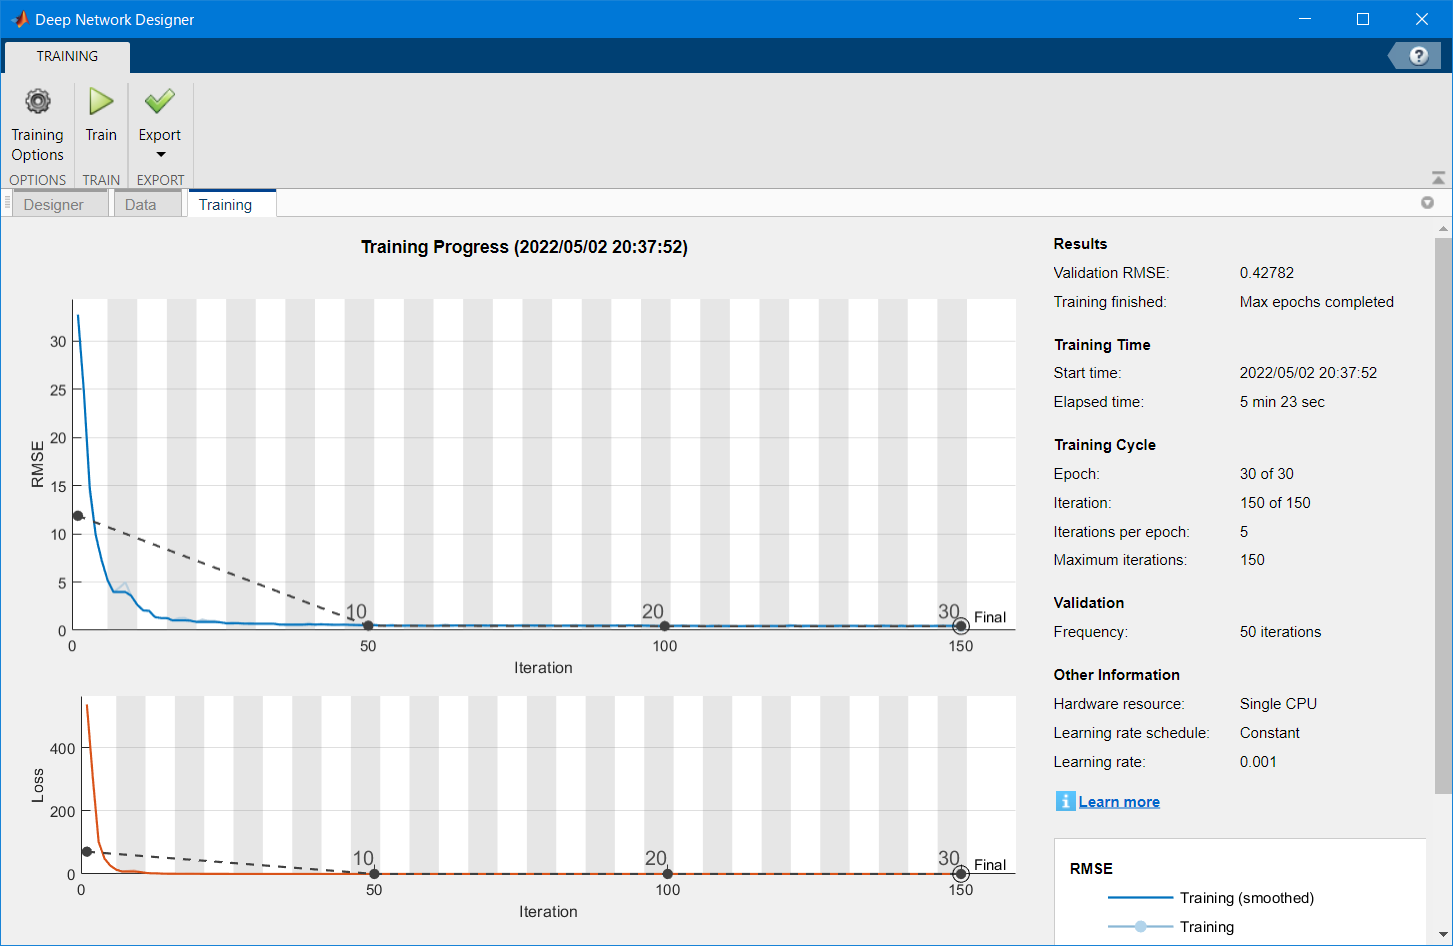

## Confirmation of model

Click Export> Export Trained Network and Results to export the network to your workspace.

Let's check the model using the verification data. (Blue: Steering prediction by learning model, Red: Steering verification data)

figure;
tmp = predict(trainedNetwork_1,ValidationData);
plot([tmp,ang(trainN+1:dataN)']);

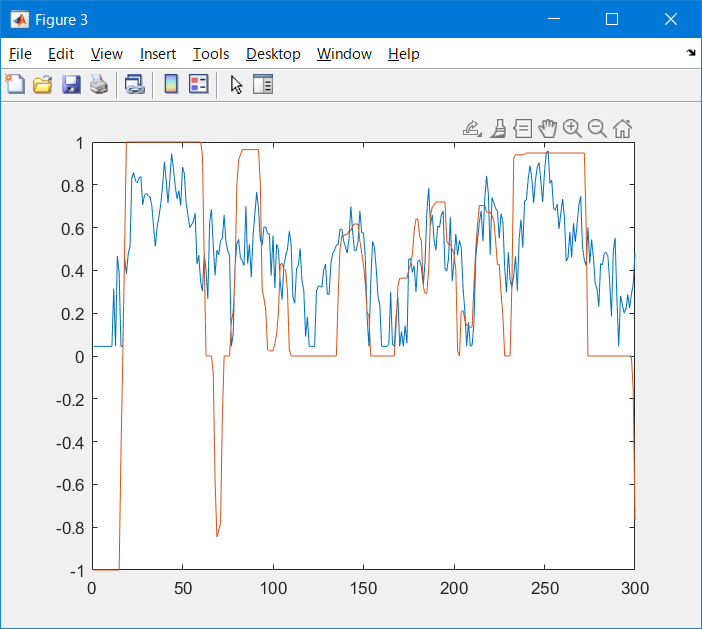

## Reference

- [Donkey Car User Guide>Dataset and pre-trained models](https://docs.donkeycar.com/guide/dataset_pretrained_models/)

- [Implementing Network Lag for Keras Linear with DonkeyCar](https://handykurniawan.medium.com/implementing-network-lag-for-keras-linear-with-donkeycar-43fd726c2afe)